    **     Physics informed Neural Networks (TMDD model without dosing).**

Here we will start with the example of basic target mediated drug disposition model and using physics informed neural network to generate the underlying neural network model and compare the simulation results

numInitialConditionPoints = 1;

t0IC = zeros(1,numInitialConditionPoints);
T0IC = 10;
C0IC = 0;
D0IC = 5;
% Grouping together data for initial and boundary conditions

% Select 10,000 points to enforce the output of the network to fulfill the
% TMDD coupled equations
numInternalCollocationPoints = 10000;

pointSet = sobolset(1); % This just create sequence of random numbers (first dimension is X and second dimension is t).
points = net(pointSet,numInternalCollocationPoints);

dataT = points.*10;% Ranges from 0 to 1

% Creating an array datastore containing the training set
ds = arrayDatastore(dataT);

Let's start to define the Deep Learning Model

We define a multilayer perception architecture with 9 fully connect operations and 20 hidden neurons. The first fully connect operation has one input channels corresponding to the input t. The last fully connect operation has three output T(t), C(t) and D(t).

numLayers = 9;
numNeurons = 20;
% Initialize the parameters for the first fully connect operation. The first fully connect operation has two input channels.
parameters = struct;
sz = [numNeurons 1];
parameters.fc1.Weights = initializeHe(sz,1);% This function generates weights from normal distribution for 20 neurons in each layer
parameters.fc1.Bias = initializeZeros([numNeurons 1]);

Initialize the parameters for each of the remaining intermediate fully connect operations.

for layerNumber=2:numLayers-1% looping over number of layers except the first and last layer.
    name = "fc"+layerNumber;
    sz = [numNeurons numNeurons];
    numIn = numNeurons;
    parameters.(name).Weights = initializeHe(sz,numIn);
    parameters.(name).Bias = initializeZeros([numNeurons 1]);
end

Initialize the parameters for the final fully connect operation. The final fully connect operation has three output channel. Three output channels are the concentration of different species

sz = [3 numNeurons];
numIn = numNeurons;
parameters.("fc" + numLayers).Weights = initializeHe(sz,numIn);
parameters.("fc" + numLayers).Bias = initializeZeros([3 1]);

Let's now define Model and Model loss Functions. We will train the model for 3000 epochs with a mini-batch size of 1000.

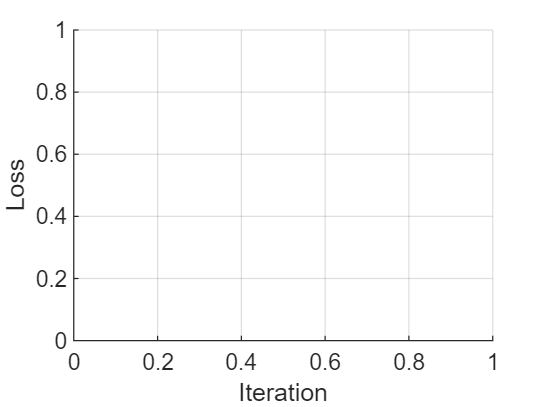

numEpochs = 1000;%1000 is good. Reducing it to 500 did not give good match
miniBatchSize = 1000;% Change plot to log scale
% Specify ADAM optimization options
initialLearnRate = 0.01;
decayRate = 0.005;
%% We can train the network now
mbq = minibatchqueue(ds, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFormat="BC");
% Convert the intial and boundary conditions to dlarray.
t0 = dlarray(t0IC,"CB");
T0 = dlarray(T0IC);
C0 = dlarray(C0IC);
D0 = dlarray(D0IC);
% Initialize the parameters for the Adam solver.
averageGrad = [];
averageSqGrad = [];
% Accelerate the model loss function using the dlaccelerate function
accfun = dlaccelerate(@modelLoss);
% Initialize the training progress plot.
figure
C = colororder;
lineLoss = animatedline(Color=C(2,:));
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

Train the network. For each iteration

-  Read a mini-batch of data from the mini-batch queue.

- Evaluate the model loss and gradients using the accelerated model loss and dlfeval functions.

- Update the learning rate.

- Update the learnable parameters using the adamupdate function.

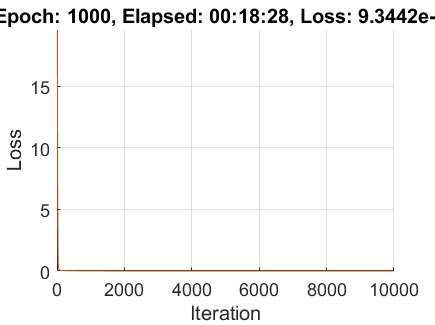

start = tic;

iteration = 0;

for epoch = 1:numEpochs
    reset(mbq);

    while hasdata(mbq)
        iteration = iteration + 1;

        T1 = next(mbq);% Out of 10000 total data set, you can use next function to obtain mini-batches from mbq. 
        % The actual data is saved in dataX and dataT. You can compare the
        % first 1000 enteries of dataX and dataT and XT for confirmation.

        % Evaluate the model loss and gradients using dlfeval and the
        % modelLoss function.
        [loss,gradients] = dlfeval(accfun,parameters,T1,t0,T0,C0,D0);

        % Update learning rate.
        learningRate = initialLearnRate / (1+decayRate*iteration);

        % Update the network parameters using the adamupdate function.
        [parameters,averageGrad,averageSqGrad] = adamupdate(parameters,gradients,averageGrad, ...
            averageSqGrad,iteration,learningRate);
    end
    loss;
    % Plot training progress.
    loss = double(gather(extractdata(loss)));
    addpoints(lineLoss,iteration, loss);

    D = duration(0,0,toc(start),Format="hh:mm:ss");
    title("Epoch: " + epoch + ", Elapsed: " + string(D) + ", Loss: " + loss)
    drawnow
end

Let's compare with the actual solution

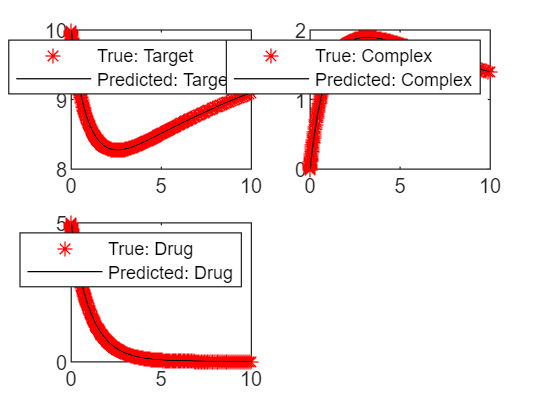

numPredictions = 1001;
TTest = linspace(0,10,numPredictions);

figure
% Make predictions.
TTest = dlarray(TTest,"CB");
Pred = model(parameters,TTest);
TPred = Pred(1,:);
CPred = Pred(2,:);
DPred = Pred(3,:);
% Calculate true values.
% Import it from Data saved using SimBio
results = load('Data.txt');
Time = load('Time.txt');
% Calculate error.
errT = norm(extractdata(TPred) - results(:,1)) / norm(results(:,1));
errC = norm(extractdata(CPred) - results(:,2)) / norm(results(:,2));
errD = norm(extractdata(DPred) - results(:,3)) / norm(results(:,3));
% Plot predictions.
subplot(2,2,1)
plot(Time,results(:,1),'*r',extractdata(TTest),extractdata(TPred),'-k')
legend("True: Target","Predicted: Target")
subplot(2,2,2)
plot(Time,results(:,2),'*r',extractdata(TTest),extractdata(CPred),'-k')
legend("True: Complex","Predicted: Complex")
subplot(2,2,3)
plot(Time,results(:,3),'*r',extractdata(TTest),extractdata(DPred),'-k')
legend("True: Drug","Predicted: Drug")